# Calcolo Numerico con Laboratorio

# Compito a casa 

# 6 dicembre 2021

## Esercizio 1

Si consideri l'equazione differenziale


$$y'=2\frac{y}{t}+t+1\quad t\in[1/e,2],\qquad y(1/e)=-\frac{e+1}{e^2}$$


la cui soluzione è $y(t)=t^2\log(t)-t$.

Scrivere un programma di tipo script che esegua le seguenti istruzioni.

Posto `N=[10 20 40 80 160 320]`,

- per ogni valore di N, calcolare usando la function RK4 la soluzione dell'equazione differenziale data;

- per ogni valore di N, riportare il grafico della soluzione esatta e della soluzione approssimata in una stessa figura (aggiungere la legenda e il titolo);

- per ogni valore di N, calcolare l'errore ottenuto;

- plottando l'errore in un grafico in scala bilogaritmica, verificare che il metodo è del quarto ordine.

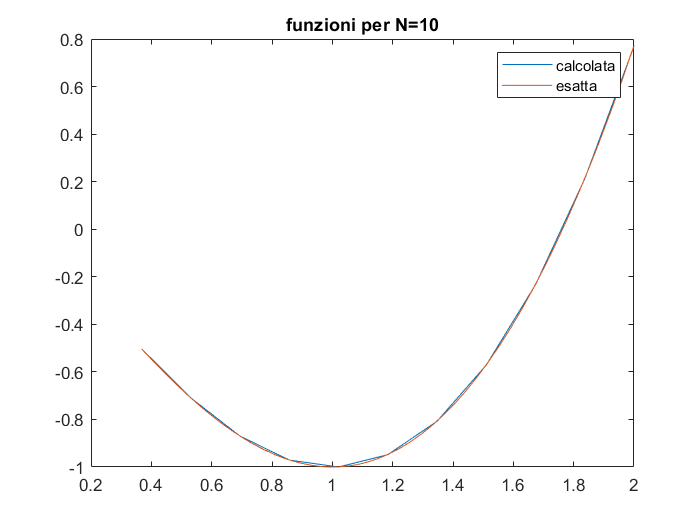

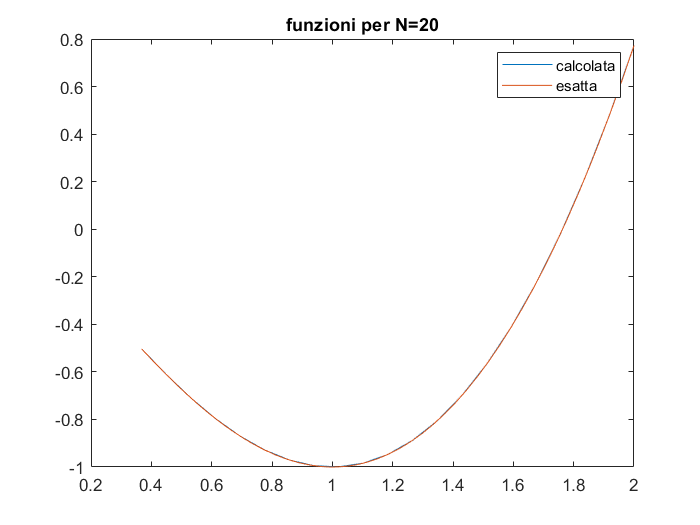

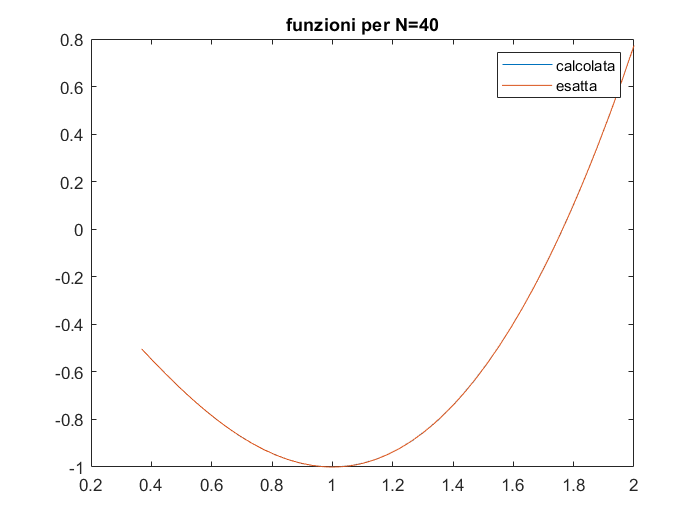

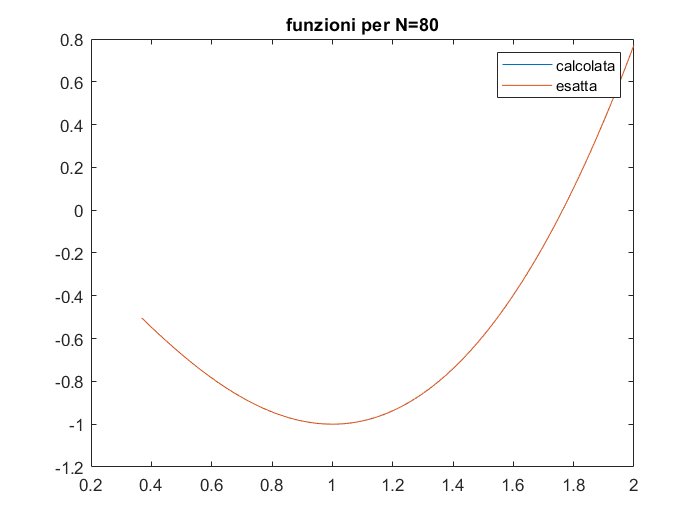

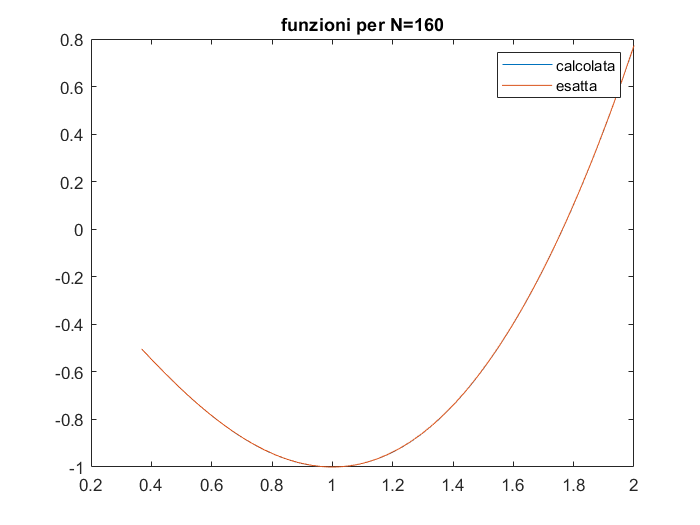

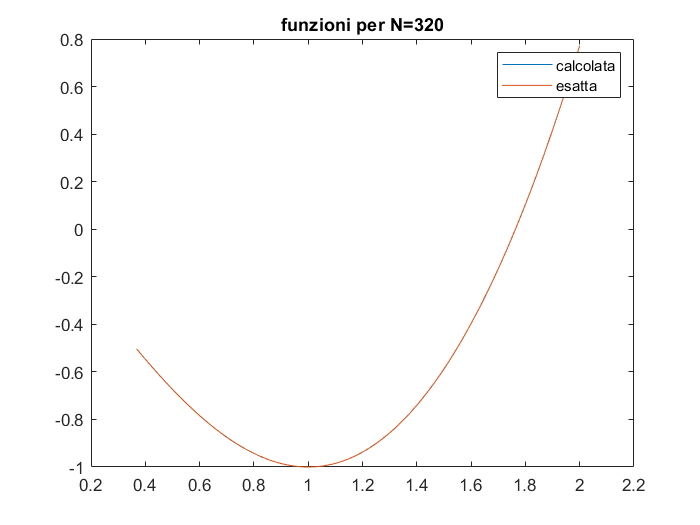

clear all
close all
N=[10 20 40 80 160 320];
f1=@(t,y) 2*y./t+t+1;
t0=1/exp(1);T=2;y0=-(exp(1)+1)/exp(2);
ft=@(t) t.^2.*log(t)-t;
E=[];
H=[];
for n=N
    H=[H ((T-t0)/n)^4];
    [t,u]=RK4(f1,t0,T,y0,n);
    figure 
    plot(t,u)
    hold on
    fplot(ft,[t0 T])
    title("funzioni per N="+n)
    legend("calcolata","esatta")
    savefig("Es1_funzioni per N="+n)
    E=[E norm(ft(t)-u,"inf")];
end

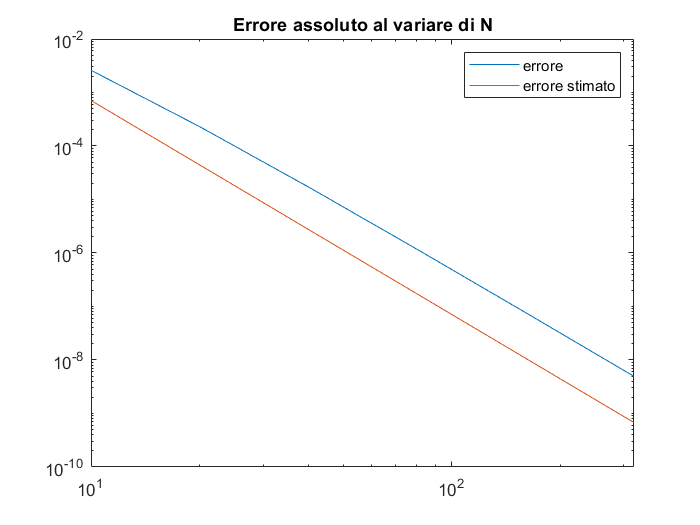

figure
loglog(N,E,N,H)
legend("errore","errore stimato")
title("Errore assoluto al variare di N")
savefig("Es1_Errore assoluto al variare di N")

## Esercizio 2

Risolvere il problema modello


$$y'=\lambda y, t\in[0,20],\qquad y(0)=1$$


per $\lambda=-10$.

Tenuto conto dei risultati sulla regione di assoluta stabilità, trovare sperimentalmente il valore più piccolo di $N$ per il quale le function `Heun`, `RK4`,`AB2` e `AM3` forniscono una soluzione tendente a 0 al crescere di $t_n$.

In base ai risultati ottenuti qual è il valore massimo di $|\lambda h|$ per i metodi considerati?

clear all
close all
lambda=-10;
f1=@(t,y) lambda*y;t0=0;T=20;y0=1;
N=[20 40 80 160 320];
LH=[];
disp("1 - Heun")

1 - Heun


disp("2 - RK4")

2 - RK4


disp("3 - AB2")

3 - AB2


disp("4 - AM3")

4 - AM3


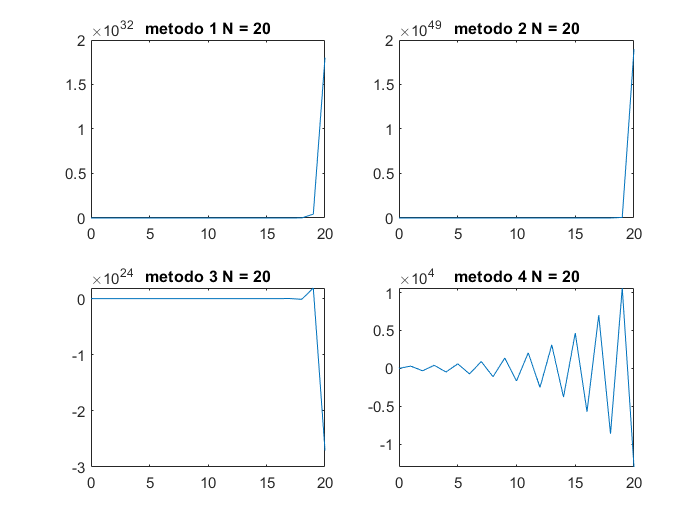

    10



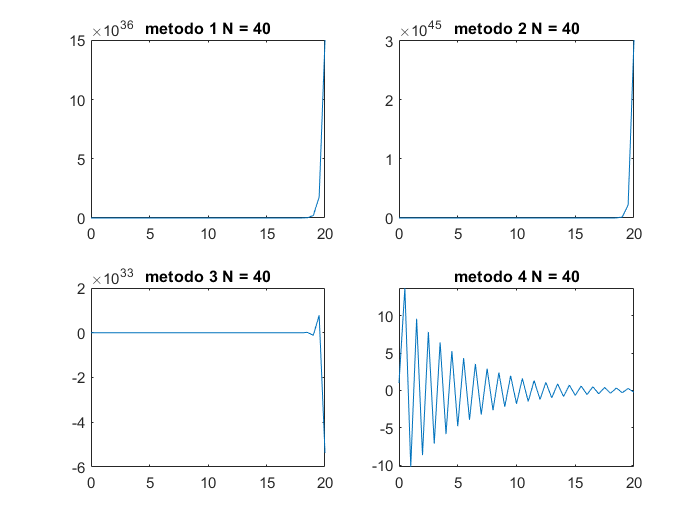

     5



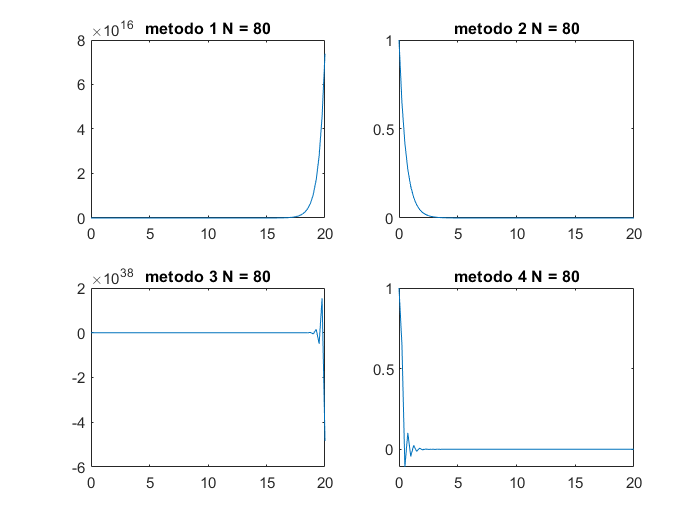

    2.5000



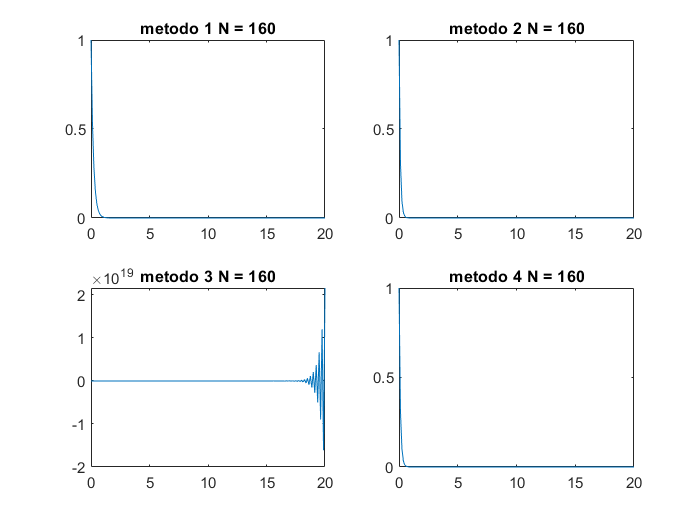

    1.2500



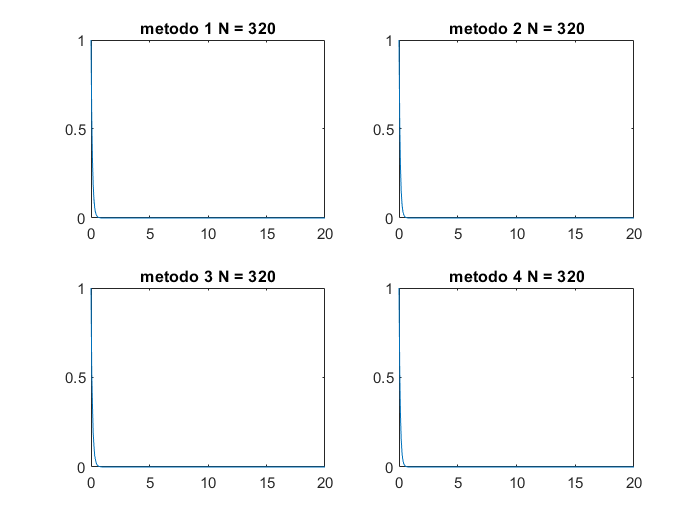

    0.6250



for n=N
    t=[];u=[];
    LH=[LH abs(lambda*(T-t0)/n)];
    [t(1,:),u(1,:)]=Heun(f1,t0,T,y0,n);
    [t(2,:),u(2,:)]=RK4(f1,t0,T,y0,n);
    [t(3,:),u(3,:)]=AB2(f1,t0,T,y0,n);
    [t(4,:),u(4,:)]=AM3(f1,t0,T,y0,n);
    figure
    for i=1:4
        subplot(2,2,i)
        plot(t(i,:),u(i,:))
        title("metodo "+i+" N = "+n)
        
    end
    savefig("Es2_metodo "+i+" N = "+n)
    disp(abs(lambda*(T-t0)/n))
end

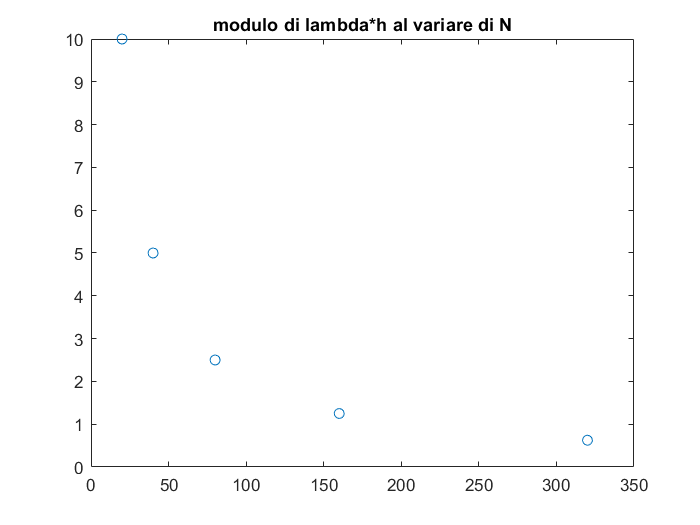

figure
plot(N,LH,'o')
title("modulo di lambda*h al variare di N")
savefig("Es2_modulo di lambdah al variare di N")

N=34;
[t,u]=AM3(f1,t0,T,y0,N);
subplot(2,2,1)
plot(t,u)
title("AM3")
disp(abs(lambda*(T-t0)/N))

    5.8824



N=72;
[t,u]=RK4(f1,t0,T,y0,N);
subplot(2,2,2)
plot(t,u)
title("RK4")
disp(abs(lambda*(T-t0)/N))

    2.7778



N=101;
[t,u]=Heun(f1,t0,T,y0,N);
subplot(2,2,3)
plot(t,u)
title("Heun")
disp(abs(lambda*(T-t0)/N))

    1.9802



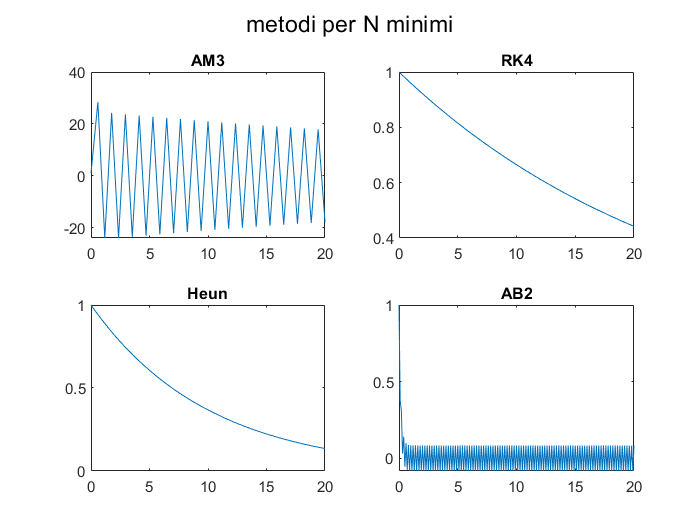

N=200;
[t,u]=AB2(f1,t0,T,y0,N);
subplot(2,2,4)
plot(t,u)
title("AB2")
sgtitle("metodi per N minimi")
savefig("Es2_metodi per N minimi")

disp(abs(lambda*(T-t0)/N))

     1



## Esercizio 3

Si consideri il modello *preda-predatore *di Lotka-Volterra:


$$\begin{array}{l}y'_1(t)=2y_1(t)-\alpha y_1(t) y_2(t)\\y'_2(t)=-y_2(t)+\alpha y_1(t) y_2(t)\end{array}$$


con $y_1(0)=y_{01}$ e $y_2(0)=y_{02}$.

Calcolare la soluzione usando `ode45` nell'intervallo $[0,50]$ con i seguenti valori dei dati: $\alpha=0.01$, $y_{01}=300$ e $y_{02}=150$.

Nel caso in cui la soluzione non sia perfettamente periodica, porre la tolleranza relativa uguale a `1e-6`.

Il seguente modello modificato tiene conto del fatto che la famiglia delle prede non può crescere indefinitamente in assenza dei predatori


$$\begin{array}{l}y'_1(t)=2\left(1-\frac{y_1(t)}R\right)y_1(t)-\alpha y_1(t) y_2(t)\\y'_2(t)=-y_2(t)+\alpha y_1(t) y_2(t)\end{array}$$


Calcolare la soluzione del modello modificato con gli stessi dati di prima e $R=400$.

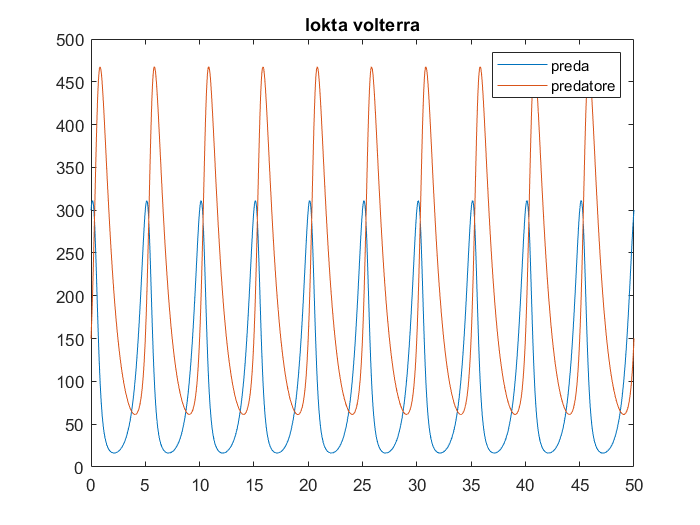

clear all
close all
t0=0;T=50;alpha=0.01;y01=300;y02=150;
F=@(t,y) [2*y(1)-alpha*y(1).*y(2);-y(2)+alpha*y(1).*y(2)];
opt=odeset("RelTol",1e-6);
[t,u]=ode45(F,[t0 T],[y01;y02],opt);
plot(t,u)
legend("preda","predatore")
title("lokta volterra")
savefig("Es3_lokta volterra")

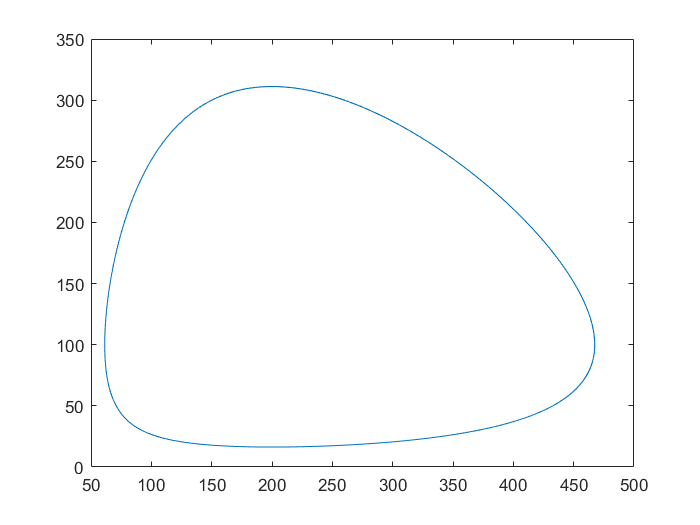

plot(u(:,2),u(:,1))

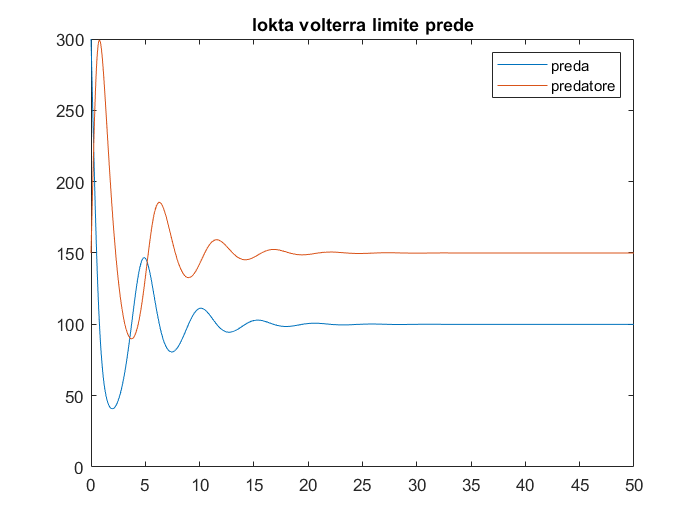


R=400;
F1=@(t,y) [2*y(1).*(1-y(1)/R)-alpha*y(1).*y(2);-y(2)+alpha*y(1).*y(2)];
opt=odeset("RelTol",1e-6);
[t,u]=ode45(F1,[t0 T],[y01;y02],opt);
plot(t,u)
legend("preda","predatore")
title("lokta volterra limite prede")
savefig("Es3_lokta volterra limite prede")

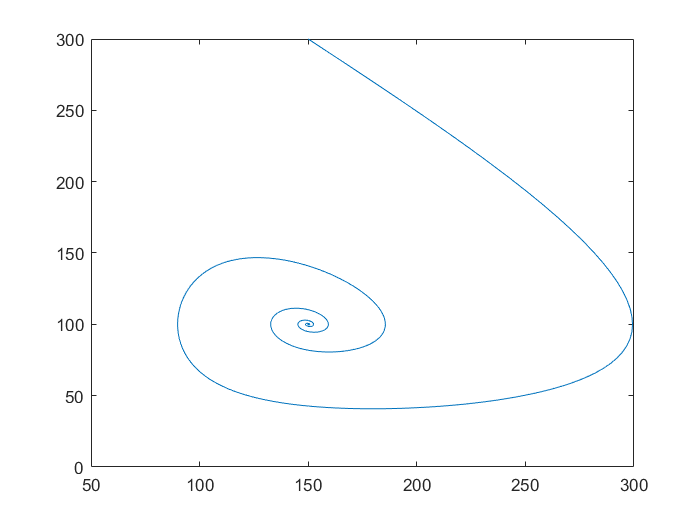

plot(u(:,2),u(:,1))